# **Matriz de observabilidad**

Un sistema de suspensión activa se puede modelar como

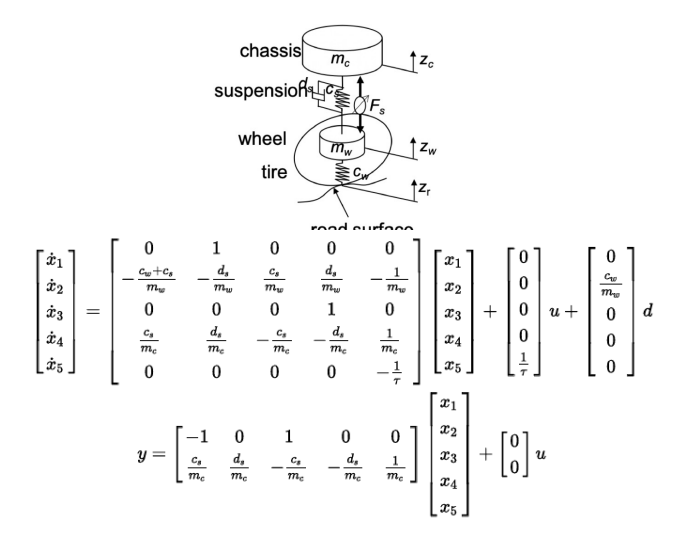

donde x1 es la posición de la rueda, x2 es la velocidad de la rueda, x3 es la posición del chasis, x4 es la velocidad del chasis y x5 es la fuerza del actuador. d es la perturbación del sistema, la posición de la superficie del terreno.

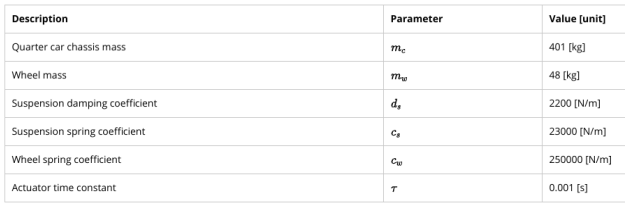

**1)** Encuentre la matriz de observabilidad. ¿Es el sistema observable?. 

close all; clear all; clc;
% Parámetros del sistema.
mc=401;                         % Quarter car mass [kg]
mw=48;                          % Wheel mass [kg]
ds=2200;                        % Suspension damping coefficient [Ns/m]
cs=23000;                       % Suspension spring coefficient [N/m]
cw=250000;                      % Wheel spring coefficient [N/m]
tau=0.001;                      % Actuator time constant [s]
% Matrices del sistema.
A=[0            1      0      0      0;
   -(cw+cs)/mw -ds/mw  cs/mw  ds/mw -1/mw;
   0            0      0      1      0;
   cs/mc        ds/mc -cs/mc -ds/mc  1/mc;
   0            0      0      0     -1/tau];
B=[0 0 0 0 1/tau]';
H=[0 cw/mw 0 0 0]';
C=[-1    0      1      0     0;
   cs/mc ds/mc -cs/mc -ds/mc 1/mc];   
observabilidad = obsv(A,C); % Matriz de observabilidad.
if rank(observabilidad) == 5
    fprintf('Rango de la matriz de observabilidad: ')
    disp(rank(observabilidad))
    fprintf('Sistema observable.\n')
end

Rango de la matriz de observabilidad: 

     5



Sistema observable.


**2)** Verifique si el sistema es observable si solamente se mide la compresión del amortiguador, 

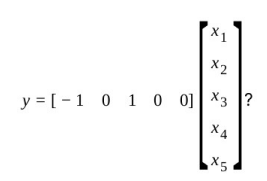

Cprima = [-1 0 1 0 0];
observabilidad = obsv(A,Cprima); % Matriz de observabilidad.
if rank(observabilidad) == 5
    fprintf('Rango de la matriz de observabilidad para C = [-1 0 1 0 0]: ')
    disp(rank(observabilidad))
    fprintf('El sistema es observable a partir de medir la\ncompresión del amortiguador.\n')
else
    fprintf('El sistema no es observable para C = [-1 0 1 0 0],\nesto implica que no podremos estimar los estados\ninternos del sistema a partir de medir la compresión\ndel amortiguador.\n')
end

Rango de la matriz de observabilidad para C = [-1 0 1 0 0]: 

     5



El sistema es observable a partir de medir la
compresión del amortiguador.


En este caso la matriz de observabilidad no resulta cuadrada sino que resulta de 10x5, con lo cual en este caso el rango de la matriz es el rango de matriz cuadrada más grande que se puede formar.

**3)** Verifique si el sistema es observable si solamente se mide la posición de la rueda, 

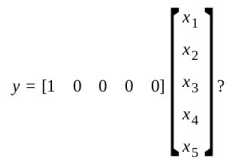

Cprima = [1 0 0 0 0];
observabilidad = obsv(A,Cprima); % Matriz de observabilidad.
if rank(observabilidad) == 5
    fprintf('Rango de la matriz de observabilidad para C = [1 0 0 0 0]: ')
    disp(rank(observabilidad))
    fprintf('El sistema es observable a partir de medir la\nposición de la rueda.\n')
else
    fprintf('El sistema no es observable para C = [1 0 0 0 0],\nesto implica que no podremos estimar los estados\ninternos del sistema a partir de medir la posición\nde la rueda.\n')
end

Rango de la matriz de observabilidad para C = [1 0 0 0 0]: 

     5



El sistema es observable a partir de medir la
posición de la rueda.


**4)** Luego de analizar los 2 escenarios posibles de observabilidad, ¿qué sensor o sensores de salida elegiría para este sistema?

Al elegir entre sensar la posición de las ruedas o la deformación de un amortiguador para estimar el estado interno de un sistema de automóvil, hay varios aspectos a considerar:

**Información sobre el comportamiento dinámico**: La posición de las ruedas proporciona información directa sobre el comportamiento dinámico del vehículo, como aceleración, frenado y cambios de dirección. Si necesitamos conocer con precisión estos aspectos, sensar la posición de las ruedas puede ser más recomendable, ya que nos brindará información detallada sobre los movimientos y la trayectoria del vehículo.

**Sensibilidad a las condiciones de la carretera:** La compresión de un amortiguador puede ser sensible a las irregularidades de la carretera y proporcionar información sobre su estado. Si la condición de la carretera es un factor crítico para nuestra aplicación, sensar la compresión del amortiguador puede ser beneficioso para adaptar el comportamiento del vehículo a las condiciones de la carretera.

**Disponibilidad y costo de los sensores**: Se debe considerar la disponibilidad y el costo de los sensores necesarios para medir tanto la posición de las ruedas como la compresión del amortiguador. Se debe además verificar la facilidad de instalación y mantenimiento de los sensores en el vehículo. Si uno de los sensores es más accesible y económico que el otro, eso también podría influir en nuestra elección.

Medir la posición de la rueda con respecto a un sistema de referencia inercial resulta extremadamente complicado de implementar, ya que si medimos con un sensor ultrasónico con respecto al suelo no estaríamos midiendo contra un sistema de referenca inercial.